# Add Paragraph to Slide Title

To add a paragraph to a slide title, use the `add` method of the `TextBoxPlaceholder` object that represents the title. This example creates a presentation with a `Title and Table` slide and then creates a second presentation from the first presentation. In the second presentation, the example adds content to the title of the `Title and Table` slide. 

Import the PPT package so that you do not have to use long, fully qualified names for the PPT API classes.

import mlreportgen.ppt.*

Create a presentation and add a `Title and Table` slide to the presentation.

ppt = Presentation("myPPT1.pptx");
open(ppt);
slide = add(ppt,"Title and Table");

Find the text box placeholder for the title and replace the content.

contents = find(slide,"Title");
replace(contents(1),"Hello World");

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the title slide in the generated presentation:

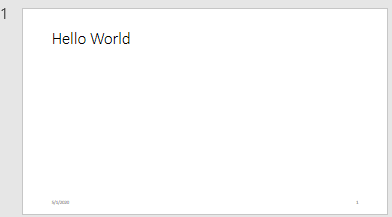

Create a second presentation, using the first presentation as the template.

ppt = Presentation("myPPT2.pptx","myPPT1.pptx");
open(ppt);

Find the text box placeholder for the title and add content to the title.

contents = find(ppt,"Title");
add(contents(1)," -- How are You?");

Close and view the presentation.

close(ppt);
rptview(ppt)

In the second presentation, the title has the content from the template presentation and the added content.

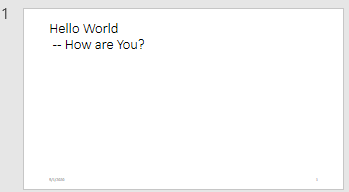

*Copyright 2020 The MathWorks, Inc.*